# Question 1

### Generation of IID location scale student t [v=4, location=1, scale=2]

alpha=0.01;
confidence_level = 0.9;
rep = 100;
B = 300;
T = [100,500,2000];

% parameters of t-dist [df, location, scale]
param = [4,0,2];
% Calculate true ES
trueES1 = ES_t(param,alpha);

% Arrays to store actual coverage array and confidence interval lengths
% Size 3 x number of reps
bool_nonparam_1 = zeros(3,rep);
length_nonparam_1 = zeros(3,rep);
bool_param_1 = zeros(3,rep);
length_param_1 = zeros(3,rep);

for i=1:length(T)
    % for each value of T
    % calculate parametric and non parametric coverage and CI lengths
    % args = [distribution name, its param, T, rep, B, true_ES, alpha, confidence_level, parametric distribution]
    [a,b,c,d] = repetition("T",param,T(i),rep,B,trueES1, alpha,confidence_level,"T");
    bool_nonparam_1(i,:)= a;
    length_nonparam_1(i,:)= b;
    bool_param_1(i,:) =c;
    length_param_1(i,:) =d;
end

for i=1:length(T)
    disp("T length = "+T(i));
    disp("non-parametric:");
    disp("   coverage: "+sum(bool_nonparam_1(i,:))/rep+" | average CI length:"+sum(length_nonparam_1(i,:))/rep);
    disp("parametric: " ); ...
    disp("   coverage: "+sum(bool_param_1(i,:))/rep   +" | average CI length:"+sum(length_param_1(i,:))/rep);
    disp(" "+newline);
end

T length = 100


non-parametric:


   coverage: 0.28 | average CI length:4.283


parametric: 


   coverage: 0.88 | average CI length:13.2791


T length = 500


non-parametric:


   coverage: 0.75 | average CI length:5.086


parametric: 


   coverage: 0.89 | average CI length:4.3852


T length = 2000


non-parametric:


   coverage: 0.87 | average CI length:3.2458


parametric: 


   coverage: 0.87 | average CI length:2.1458


# Question 3

### Bootstrap for Stable alpha = 1.6

% Stable parameters
param = [1.6,0,1,0];
% Calculate true ES
[trueES2_1,VaR] = ES_stable(alpha, param);
% Create distribution object for random data generation in repetition()
pdist2_1 = makedist("Stable",param(1),param(2),param(3),param(4));

% Arrays to store actual coverage array and confidence interval lengths
% Size 3 x number of reps
bool_nonparam_2_1 = zeros(3,rep);
length_nonparam_2_1 = zeros(3,rep);
bool_param_2_1 = zeros(3,rep);
length_param_2_1 = zeros(3,rep);

for i=1:length(T)
    % for each value of T
    % calculate parametric and non parametric coverage and CI lengths
    % args = [distribution name, its param, T, rep, B, true_ES, alpha, confidence_level, parametric distribution]
    [a,b,c,d] = repetition(pdist2_1,T(i),rep,B,trueES2_1, alpha,confidence_level,"T");
    bool_nonparam_2_1(i,:)= a;
    length_nonparam_2_1(i,:)= b;
    bool_param_2_1(i,:) =c;
    length_param_2_1(i,:) =d;
end

for i=1:length(T)
    disp("T length = "+T(i));
    disp("non-parametric:");
    disp("   coverage: "+sum(bool_nonparam_2_1(i,:))/rep+" | average CI length:"+sum(length_nonparam_2_1(i,:))/rep);
    disp("parametric: " ); ...
    disp("   coverage: "+sum(bool_param_2_1(i,:))/rep   +" | average CI length:"+sum(length_param_2_1(i,:))/rep);
    disp(" "+newline);
end

# Bootstrap for Stable alpha = 1.8

% Stable parameters
param = [1.8,0,1,0];
% Calculate true ES
[trueES2_2,VaR] = ES_stable(alpha, param);

% Arrays to store actual coverage array and confidence interval lengths
% Size 3 x number of reps
bool_nonparam_2_2 = zeros(3,rep);
length_nonparam_2_2 = zeros(3,rep);
bool_param_2_2 = zeros(3,rep);
length_param_2_2 = zeros(3,rep);

for i=1:length(T)
    % for each value of T
    % calculate parametric and non parametric coverage and CI lengths
    [a,b,c,d] = repetition("Stable",param,T(i),rep,B,trueES2_2, alpha,confidence_level, "T");
    bool_nonparam_2_2(i,:)= a;
    length_nonparam_2_2(i,:)= b;
    bool_param_2_2(i,:) =c;
    length_param_2_2(i,:) =d;
end

for i=1:length(T)
    disp("T length = "+T(i));
    disp("non-parametric:");
    disp("   coverage: "+sum(bool_nonparam_2_2(i,:))/rep+" | average CI length:"+sum(length_nonparam_2_2(i,:))/rep);
    disp("parametric: " ); ...
    disp("   coverage: "+sum(bool_param_2_2(i,:))/rep   +" | average CI length:"+sum(length_param_2_2(i,:))/rep);
    disp(" "+newline);
end

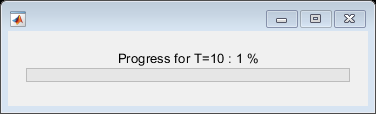

% Stable parameters
param = [1.6,0,1,0];
% Calculate true ES of stable dist
[trueES,VaR] = ES_stable(alpha, param);

T= [10];
% Arrays to store actual coverage array and confidence interval lengths
% Size 3 x number of reps
bool_nonparam= zeros(3,rep);
length_nonparam = zeros(3,rep);
bool_param = zeros(3,rep);
length_param = zeros(3,rep);


for i=1:length(T)
    % for each value of T
    % calculate parametric and non parametric coverage and CI lengths
    % args = [distribution name, its param, T, rep, B, true_ES, alpha, confidence_level, parametric distribution]
    [a,b,c,d] = repetition("Stable",param,T(i),rep,B,trueES, alpha,confidence_level,"T");
    bool_nonparam(i,:)= a;
    length_nonparam(i,:)= b;
    bool_param(i,:) =c;
    length_param(i,:) =d;
end